matlab manual stereo param calculation

%% Stereo Camera Calibration Script
% This script calibrates a stereo camera setup given two folders of
% left and right checkerboard images.

%% --- USER INPUTS ---
% Set paths to your left and right image folders
leftFolder  = "C:\Users\yohan\OneDrive\Documents\Research Stuff\Squid Analysis\Nikon Data Analysis\Squid Sighting 6-12\Calib Data 6-12\Left Images";
rightFolder = "C:\Users\yohan\OneDrive\Documents\Research Stuff\Squid Analysis\Nikon Data Analysis\Squid Sighting 6-12\Calib Data 6-12\Right Images";

% Define image file extensions
fileExtension = '*.jpg';  % or '*.jpg', '*.tif', etc.

% Define checkerboard square size in millimeters (or any consistent unit)
squareSize = 25;  % e.g., 25 mm squares

%% --- LOAD IMAGE FILES ---
leftImages  = imageDatastore(fullfile(leftFolder, fileExtension));
rightImages = imageDatastore(fullfile(rightFolder, fileExtension));

% Check that the number of images match
if numel(leftImages.Files) ~= numel(rightImages.Files)
    error('Number of left and right images must be the same!');
end

%% --- DETECT CHECKERBOARD CORNERS ---
[imagePoints, boardSize, pairsUsed] = detectCheckerboardPoints( ...
    leftImages.Files, rightImages.Files,'HighDistortion',true);


fprintf('Detected checkerboard in %d valid stereo pairs.\n', sum(pairsUsed));

Detected checkerboard in 1 valid stereo pairs.


% Read one image to get image size
I = readimage(leftImages, 1);
imageSize = [size(I, 1), size(I, 2)];

%% --- GENERATE WORLD COORDINATES OF CHECKERBOARD POINTS ---
worldPoints = generateCheckerboardPoints(boardSize, squareSize);
%imagePoints(:,:,3,:) = [];

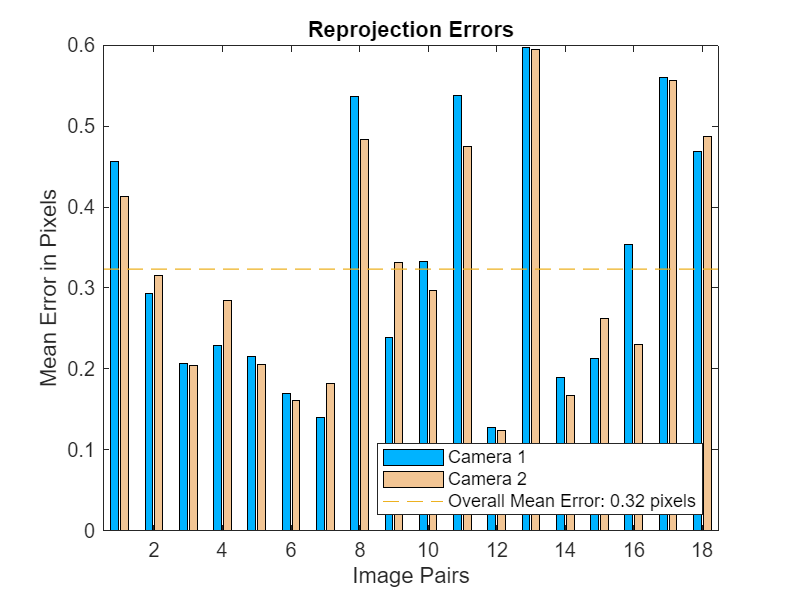

%% --- CALIBRATE STEREO SYSTEM ---
stereoParams = estimateCameraParameters(imagePoints, worldPoints, ...
    'ImageSize', imageSize, ...
    'EstimateSkew', false, ...
    'EstimateTangentialDistortion', true, ...
    'NumRadialDistortionCoefficients', 2, ...
    'WorldUnits', 'mm');

%% --- DISPLAY RESULTS ---
% Show reprojection errors
figure;
showReprojectionErrors(stereoParams);
title('Reprojection Errors');

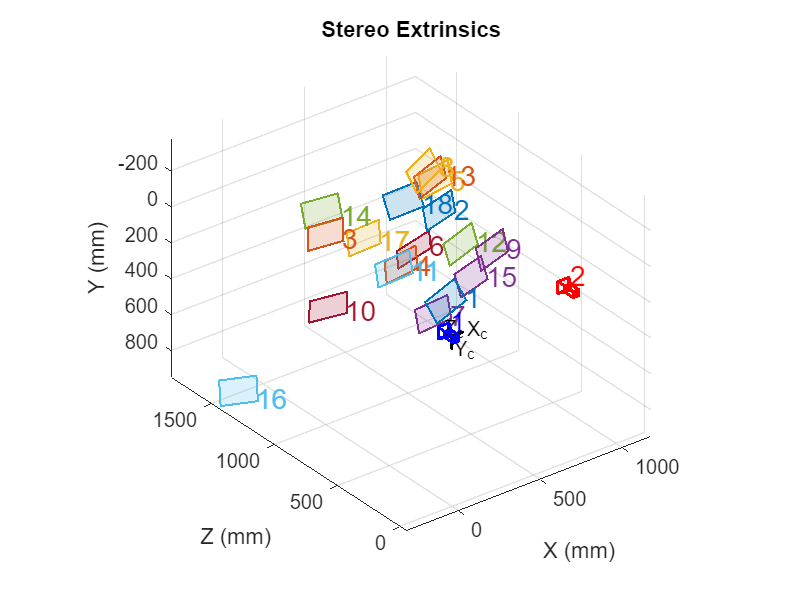


% Show extrinsics
figure;
showExtrinsics(stereoParams, 'CameraCentric');
title('Stereo Extrinsics');

%% --- SAVE RESULTS ---
save('stereoParams.mat', 'stereoParams');
fprintf('Stereo calibration complete! Parameters saved to stereoParams.mat\n');

Stereo calibration complete! Parameters saved to stereoParams.mat
